# IMPORT DATA

close all
clc
clear all

dir = pwd;
addpath("Functions\");
wind_data = readtable(strcat(dir, '\Data\Wind_data.csv')).WindSpeed_m_s_;    %already access the table

Remove NaN from data

wind_data = wind_data(~isnan(wind_data));

Turbine data

rho_air = 1.225;            % air density [kg/m3]
H = 119;                    % hub height [m]
R_rotor = 178.3/2;               % rotor radius [m]
A_rotor = pi*R_rotor^2;     % rotor area [m2]
V_rated = 11.4;               % rated wind speed [m/s]
V_ci = 4;                   % cut-in wind speed [m/s]
V_co = 25;
Jeq = 1.56e8;                % equivalent inertia [kg*m2]
b = 2e5;                  % damping (equivalent losses) coefficient [N*m*s/rad]
P_rated = 10e6;             % rated power [W]
pole_pairs = 320;           % poles pairs
magnets_flux = 19.49;       % magnets flux [Wb]
stat_resistance = 64e-3;    % stator resistance [ohm]



% Cp-lambda curve
%CpL = load(strcat(dir, '\Data\Cp_Burton.csv'));
%Cp = spline(CpL(:, 1), CpL(:, 2));
%ppval(Cp, 3) %test

## PDF ANALYSYS

Calculate number of bins to use with Sturges' formula

n_bins = ceil(1 + log2(length(wind_data)))

n_bins = 18

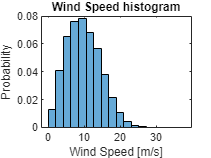


histogram(wind_data, n_bins,'Normalization','pdf')
title('Wind Speed histogram')
xlabel('Wind Speed [m/s]')
ylabel('Probability')

Now we can fit the weibull distribution. No confidence interval is specified so it will be assumed to 95%

weibull_coeff = wblfit(wind_data);

disp(['Weibull distrivution coefficients: shape k = ', num2str(weibull_coeff(1)),'; scale λ = ', num2str(weibull_coeff(2))]);

Weibull distrivution coefficients: shape k = 11.1661; scale λ = 2.2131


Plot the distribution

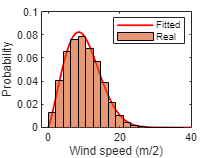

x = linspace(0, 40);

plot(x, wblpdf(x, weibull_coeff(1), weibull_coeff(2)), 'r', 'LineWidth', 1.5)
hold on
histogram(wind_data, n_bins,'Normalization','pdf')
legend('Fitted', 'Real')
xlabel('Wind speed (m/2)')
ylabel('Probability')

## Stall regulated turbine

Constant speed, no pitch control.

Find the proper rotation speed omega. We can find this by imposing the lambda at which we have max Cp (usually at Cp = 0.45) and by imposing the wind speed as the AVERAGE wind speed of the year. In this way we have the max power extraction for most of the time

%% find lambda: we start by sampling the cp function, calculate its max and see at which lambda refers to
%lambda_sweep = (0.1:0.1:18)';
%Cp_sweep = ppval(Cp, lambda_sweep);
%index = find(Cp_sweep == max(Cp_sweep));
%lambda_stall_ideal = lambda_sweep(index);

%% Calculate turbine rotation speed
%omega_stall_ideal = (mean(wind_data) * lambda_stall_ideal)/R_rotor;
%omega_stall_ideal2 = (V_rated * lambda_stall_ideal)/R_rotor;

Now we have the ideal rotation speed. At this point we can calculate what is the tip speed ratio needed to maintain the ideal rotation speed as function of the wind speed.

%lambda_stall = (omega_stall_ideal * R_rotor) ./ wind_data;
%Cp_stall = ppval(Cp, lambda_stall);

Actually, to find the optimal wind turbine speed we must first observe at which speed we can reach the turbine nominal power production.

We can then do a sweep of rotation speeds, plot the power at different wind speeds and choose the one that has the power peak equal to the turbine rated power.

First start by defining a range of wind speed (for the power chart) and a range of turbine rotation speed

V_w = (0:0.1:V_co+5)';
Omega_sweep = linspace(0.75, 0.79, 10)';

At this point we can calculate the power for each omega

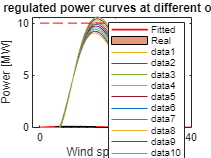

Power_sweep = zeros(length(V_w), length(Omega_sweep));

I1 = find(V_w<V_ci);
I2 = find(V_w>=V_ci & V_w<=V_co);
%I3 = find(V_w>V_rated & V_w<=V_co);
%I4 = find(V_w>V_co);

for i=1:1:length(Omega_sweep)

    lambda_stall = (Omega_sweep(i)*R_rotor)./V_w;
    Cp_stall = PowerFactor(lambda_stall, 0);
    Cp_stall(find(Cp_stall<0)) = 0;     %force negative values of Cp to zero
    Power_sweep(:, i) = 0*V_w;
    Power_sweep(I2, i) = 0.5*rho_air*V_w(I2).^3*A_rotor.*Cp_stall(I2);
    %Pw(I3) = Prated; %*ones(size(I3));

    plot(V_w, Power_sweep(:, i)/1e6)
    hold all

end

plot(V_w, repelem(10, length(V_w))', 'Color','r', 'LineStyle','--')
xlabel('Wind speed [m/s]')
ylabel('Power [MW]')
title('Stall regulated power curves at different omegas');
hold off


disp(['The ideal angular speed for the stall regulated turbine is: ', num2str(0.776),' [rad/s]']);

The ideal angular speed for the stall regulated turbine is: 0.776 [rad/s]


By observing the plot we find that a rotation speed of omega = 0.776 seems to have the peak at 10 MW.

We can see the power curve better.

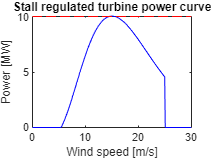

omega_stall = 0.776;
lambda_stall = (omega_stall*R_rotor)./V_w;
Cp_stall = PowerFactor(lambda_stall, 0);
Cp_stall(find(Cp_stall<0)) = 0;
Power_stall = 0*V_w;
Power_stall(I2) = 0.5*rho_air*V_w(I2).^3*A_rotor.*Cp_stall(I2);

plot(V_w, Power_stall/1e6, 'Color','b')
hold on
plot(V_w, repelem(10, length(V_w))', 'Color','r', 'LineStyle','--')
title('Stall regulated turbine power curve')
xlabel('Wind speed [m/s]')
ylabel('Power [MW]')
hold off

We can now calculate the energy produced through the year

We will first filter all the wind data with only wind speeds that are suitable to produce power. The rest will be set to zero

Energy_stall = zeros(length(wind_data), 1);
wind_speed_stall = wind_data;
wind_speed_stall(find(wind_speed_stall < V_ci)) = 0;
wind_speed_stall(find(wind_speed_stall > V_co)) = 0;
lambda_stall_year = (omega_stall*R_rotor)./wind_speed_stall;
Cp_stall_year = PowerFactor(lambda_stall_year, 0);
Cp_stall_year(find(Cp_stall_year<0)) = 0;
Energy_stall = (1/6)*0.5*rho_air*wind_speed_stall.^3*A_rotor.*Cp_stall_year;

We have now the vector with the energy produced every 10 minutes. To obtain the average energy produced in a year there are 2 ways:

    - calculate the mean and multiply it by 6 (10 minutes times 6 makes an hour)

    - group the vector in groups of 6, sum these smaller vectors and calculate the total mean

We expect it to be the same but both methods will be implemented just to make sure

%Method 1
Energy_stall_mean_1 = mean(Energy_stall)*6;

%Method 2
Energy_stall_temp = reshape(Energy_stall, [], 6);   %matrix with the hourly energy set in rows
Energy_stall_mean_2 = mean(sum(Energy_stall_temp, 2));

We can go on further and calculate the total energy produced in 1 year. Keep in mind that the data covers 2 years.

Start by calculating the energy, which we can consider as the area under the power evolution curve.

We first divide the area by 6 because of the W per 10m to Wh conversion, and then divide by 2 because we consider only 1 year

Energy_stall_total = (sum(0.5*rho_air*wind_speed_stall.^3*A_rotor.*Cp_stall_year)/6)/2;

Now if we want to calculate the average energy production in 1 hour, we divided what calculated above by the number of hours in a year

Energy_stall_hourly_avg = Energy_stall_total / (24*365);

disp(['Stall regulated turbine yearly energy production: ',num2str(Energy_stall_total/1e6),' [MWh]']);

Stall regulated turbine yearly energy production: 44134.7528 [MWh]


disp(['Stall regulated turbine average hourly energy production: ',num2str(Energy_stall_hourly_avg/1e6),' [MWh]']);

Stall regulated turbine average hourly energy production: 5.0382 [MWh]


## Pitch regulated turbine

First of all, we need to find a target tip speed ratio to maximize the power factor.

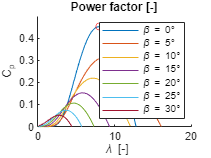

%% POWER FACTOR MAP
% The map is used only for visualizing the plot, in the model the fitting
% formula is used for each time instant (NOT a look-up method)

% -- BUILD AXIS
theta_vec = (0:5:30)';                   % blades pitch angle axis [deg]
lambda_sweep = (0.1:0.1:18)';              % tip speed ratio axis []    

% -- CREATE MAP
Cp_map = zeros(length(lambda_sweep),length(theta_vec));
figure
hold on
for i=1:1:length(theta_vec)
    theta = theta_vec(i);
    % -- EXPONENTIAL FITTING FORMULA
    Cp_map(:,i) = PowerFactor(lambda_sweep,theta);

    % -- SINUSOIDAL FITTING FORMULA
    % Cp_map(:,i) = (0.44 - 0.0167*theta) * sin(pi/2*(lambda_sweep-3)/(7.5-0.15*theta))-(lambda_sweep-3)*0.00184*theta;
    plot(lambda_sweep,Cp_map(:,i),'-')
    leg{i} = ['\beta = ',num2str(theta),'°'];
end
% clear('one_over_beta');

% -- FIND PEAK POWER FACTOR VALUE lambda and pitch
lambda_opt = lambda_sweep(find(~(Cp_map(:,1) - max(Cp_map(:,1)))));     % lambda corresponding to the peak (pitch = 0°)
% one_over_beta_opt = 1./(lambda_opt) - 0.035;
% Cp_opt = 0.5 * (116 * one_over_beta_opt - 5)*exp(-21*one_over_beta_opt);

Cp_opt = max(Cp_map(:,1)); %(0.44) * sin(pi/2*(lambda_opt-3)/(7.5));                       % optimal Cp
% clear('one_over_beta_opt');
Trated = Cp_opt/lambda_opt*0.5*rho_air*A_rotor.*V_rated^2*R_rotor;

plot(lambda_opt,Cp_opt,'or')
hold off
ylim([0 0.5])
title('Power factor [-]')
xlabel(' \lambda [-]')
ylabel('C_p')
legend(leg)

We now found the optimal power factor in order to maximize power extraction by acting on the turbine rotation speed.

At this point we can define the power profile of this turbine.

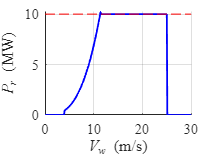

%% POWER PROFILE
% Draw the power curve turbine. Under the cut-in speed the
% power must be 0 as well as over the cut-off one. For Vw < V_rated the
% maximum available power depends on the optimal value of Cp 

V_w = (0:0.1:V_co+5)';

% working regions 
I1 = find(V_w<V_ci);
I2 = find(V_w>=V_ci & V_w<=V_rated);
I3 = find(V_w>V_rated & V_w<=V_co);
I4 = find(V_w>V_co);

Pw = 0*V_w;
Pw(I2) = 0.5*rho_air*V_w(I2).^3*A_rotor*Cp_opt;
Pw(I3) = P_rated; %*ones(size(I3));

figure;
hold on
plot(V_w,Pw/1e6,'b','linewidth',1.5)
plot(V_w, repelem(10, length(V_w))', 'Color','r', 'LineStyle','--')
grid on
xlabel('\itV_w\rm (m/s)','FontSize',12,'fontname','times new roman')
ylabel('\itP_r\rm (MW)','FontSize',12,'fontname','times new roman')
set(gca,'FontSize',12,'fontname','times new roman')
hold off

Now we can calculate the average energy production.

Just like done before, we first filter the wind data that lies outside the working range of the turbine

Energy_reg = zeros(length(wind_data), 1);
wind_speed_reg = wind_data;
wind_speed_reg(find(wind_speed_stall < V_ci)) = 0;
wind_speed_reg(find(wind_speed_stall > V_co)) = 0;
wind_speed_reg(find(wind_speed_stall > V_rated)) = V_rated;


Energy_reg = (1/6)*0.5*rho_air*wind_speed_reg.^3*A_rotor.*Cp_opt;

Energy_reg_mean = mean(Energy_reg)*6;

We can go on further and calculate the total energy produced in 1 year. Keep in mind that the data covers 2 years.

Start by calculating the energy, which we can consider as the area under the power evolution curve.

We first divide the area by 6 because of the W per 10m to Wh conversion, and then divide by 2 because we consider only 1 year

Energy_pitch_total = (sum(0.5*rho_air*wind_speed_reg.^3*A_rotor.*Cp_opt)/6)/2;

Now if we want to calculate the average energy production in 1 hour, we divided what calculated above by the number of hours in a year

Energy_pitch_hourly_avg = Energy_pitch_total / (24*365);

disp(['Stall regulated turbine yearly energy production: ',num2str(Energy_pitch_total/1e6),' [MWh]']);

Stall regulated turbine yearly energy production: 49632.1538 [MWh]


disp(['Stall regulated turbine average hourly energy production: ',num2str(Energy_pitch_hourly_avg/1e6),' [MWh]']);

Stall regulated turbine average hourly energy production: 5.6658 [MWh]


We can now see what is the average % improvement that we have with the speed regulated turbine respect to the constant speed turbine

hourly_avg_diff = (Energy_pitch_hourly_avg - Energy_stall_hourly_avg);
hourly_avg_improvement = (hourly_avg_diff/Energy_stall_hourly_avg)*100;

energy_avg_diff = (Energy_pitch_total-Energy_stall_total);
energy_avg_improvement = (energy_avg_diff/Energy_stall_total)*100;

disp(['The pitch regulated turbine produces in an hour an average of ',num2str(hourly_avg_diff/1e6),' [MWh] more respect to the stall regulated turbine', newline, ...
    'This corresponds to an improvement of ', num2str(hourly_avg_improvement), ' %.']);

The pitch regulated turbine produces in an hour an average of 0.62756 [MWh] more respect to the stall regulated turbine
This corresponds to an improvement of 12.4559 %.


disp(['The pitch regulated turbine produces in a year ',num2str(energy_avg_diff/1e6),' [MWh] more respect to the stall regulated turbine', newline, ...
    'This corresponds to an improvement of ', num2str(energy_avg_improvement), ' %.']);

The pitch regulated turbine produces in a year 5497.401 [MWh] more respect to the stall regulated turbine
This corresponds to an improvement of 12.4559 %.


We can notice we have an improvement of roughly 12.5%, which corresponds to 0.65 MWh.

## Steady state losses

Using the provided data, calculate the steady-state Joule losses (due to the windings resistances) and viscous losses (due to damping) as a function of the wind speed, and calculate the turbine average electromechanical efficiency over a year, for the case of pitch regulated variable speed turbine.

STEADY STATE: constant velocity

Calculate losses as function of wind speed due to damping and windings resistances.

We will assume that the turbine will not exceed its rated rotation speed, the power loss due to damping will be calculated only 

omega_max = (V_rated * lambda_opt)/R_rotor;
omega_sweep = (V_w .* lambda_opt)./R_rotor;
omega_sweep(find(omega_sweep>omega_max)) = omega_max;
omega_sweep(find(V_w>V_co)) = 0;
omega_sweep(find(V_w<V_ci)) = 0;

We can now calculate how the loss due to damping changes with wind speed.

Keep in mind that b*omega results in a torque, if we multiply by omega again we obtain a power, which represents the power lost due to damping.

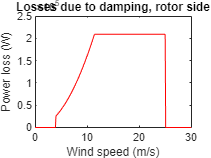

damping_loss = b* (omega_sweep.^2);

plot(V_w, damping_loss, 'Color','r')
title('Losses due to damping, rotor side')
xlabel('Wind speed (m/s)')
ylabel('Power loss (W)')

Now on the electrical side, we consider the input torque as the wind torque minus the torque loss due to damping.

After that, knowing the pole pairs and the magnets flux, we can calculate the current iq and evaluate the loss in the stator due to joule effect

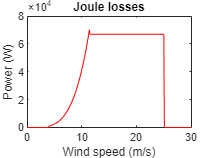

i_q = (Pw - damping_loss) ./ ((3/2) * pole_pairs * omega_sweep * magnets_flux);

% Since we have many 0/0, which result in a NaN, we replace them with zeroes
i_q(isnan(i_q)) = 0;

joule_loss = stat_resistance * i_q.^2;

plot(V_w,joule_loss, 'Color','r')
title('Joule losses')
xlabel('Wind speed (m/s)')
ylabel('Power (W)')

We can now calculate the efficiency through the year.

We start by calculating the full power and then subract the losses.

To not exceed turbine rated limits, we will impose limits on the wind speed

% full power
full_power_year = 0.5*rho_air*wind_speed_reg.^3*A_rotor.*Cp_opt;

% calculate rotation speed. Note that wind data is already filtered and
% capped to V_rated so we consider only the working range of the turbine
omega_year = (wind_speed_reg .* lambda_opt)./R_rotor;
damping_loss_year = b * omega_year.^2;

i_q_year = (full_power_year - damping_loss_year) ./ ((3/2) * pole_pairs * omega_year * magnets_flux);
i_q_year(isnan(i_q_year)) = 0;
joule_loss_year = stat_resistance * i_q_year.^2;

actual_power_year = full_power_year - damping_loss_year - joule_loss_year;

%Efficiency
turbine_eff = (mean(actual_power_year)/mean(full_power_year))*100;

disp(['In average the turbine has an efficiency of: ',num2str(turbine_eff),' %']);

In average the turbine has an efficiency of: 97.1022 %


The turbine has a 97% efficiency